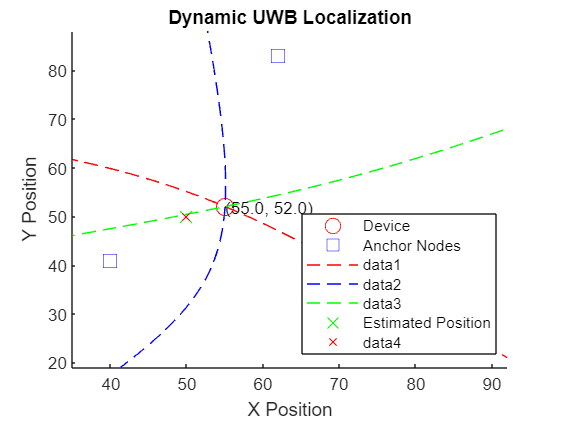

% Define initial positions for device and anchor nodes
deviceLocInitial = [50 50];  % Initial device position
nodeLocInitial = [40 41;     % Initial anchor node positions
                  62 83;
                  87 24];

% Define velocity for device (change as needed)
deviceVelocity = [0.5, 0.2];   % Velocity of the device in x and y directions

% Number of anchor nodes
numNodes = size(nodeLocInitial, 1);

% Simulation parameters
numTimeSteps = 100;  % Number of time steps for simulation
timeStep = 0.1;      % Time step duration (adjust as needed)
SNR = 10;            % Signal-to-Noise Ratio

% Initialize device and anchor node positions
deviceLoc = deviceLocInitial;
nodeLoc = nodeLocInitial;

% Initialize plot variables
figure;
hold on;
xlabel('X Position');
ylabel('Y Position');
title('Dynamic UWB Localization');
axis tight;

% Initialize plot limits
minX = min([deviceLocInitial(1), nodeLocInitial(:, 1)']);
maxX = max([deviceLocInitial(1), nodeLocInitial(:, 1)']);
minY = min([deviceLocInitial(2), nodeLocInitial(:, 2)']);
maxY = max([deviceLocInitial(2), nodeLocInitial(:, 2)']);
margin = 5; % Margin for zooming
axis([minX-margin maxX+margin minY-margin maxY+margin]);

% Plot initial positions of device and anchor nodes
devicePlot = plot(deviceLocInitial(1), deviceLocInitial(2), 'ro', 'MarkerSize', 10, 'DisplayName', 'Device');
nodePlot = plot(nodeLocInitial(:, 1), nodeLocInitial(:, 2), 'bs', 'MarkerSize', 10, 'DisplayName', 'Anchor Nodes');

% Initialize text annotation for device coordinates
deviceText = text(deviceLocInitial(1), deviceLocInitial(2), sprintf('(%.1f, %.1f)', deviceLocInitial), 'HorizontalAlignment', 'left');

% Configure Blinks
numBlinks = 1;

% MAC layer:
payload = '00'; 
cfg = lrwpan.MACFrameConfig( ...
        'FrameType', 'Data', ...
        'SourceAddressing', 'Short address', ...
        'SourcePANIdentifier', 'AB12', ...
        'SourceAddress', 'CD77');
blinkMAC = lrwpan.MACFrameGenerator(cfg, payload);

% PHY layer:
% Ensure the Ranging field is enabled. 
% Also set the proper PSDU length.
blinkPHYConfig = lrwpanHRPConfig( ...
    'Mode', 'HPRF', ...
    'STSPacketConfiguration', 1, ...
    'PSDULength', length(blinkMAC)/8, ...
    'Ranging', true);
blinkPHY = lrwpanWaveformGenerator( ...
    blinkMAC, ...
    blinkPHYConfig);

% Cache preamble, to use in preamble detection. 
% Get the 1st instance out of the Nsync=PreambleDuration repetitions.
indices = lrwpanHRPFieldIndices(blinkPHYConfig); % length (start/end) of each field
blinkPreamble = blinkPHY( ...
    1:indices.SYNC(end)/blinkPHYConfig.PreambleDuration); % 1 of the Nsync repetitions
% Run Simulation
vfd = dsp.VariableFractionalDelay;
arrivalTime = zeros(1, numNodes);

plotStr = {'r--','b--','g--'};
[x, y] = deal(cell(1, 3));

% Initialize dynamic plot handles for hyperbolas
hyperbolaPlots = gobjects(numNodes, numNodes);

% Initialize coordinates for LSTM model
coordinates = [];

for idx = 1:numBlinks
    for node = 1:numNodes
        % Transmission and reception of blink
        % Each node receives a specifically delayed version of the blink
        tof = actualTOF(node, deviceLoc, nodeLoc);
        samplesToDelay = tof * blinkPHYConfig.SampleRate;
        reset(vfd);
        release(vfd);
        % Calculate MaximumDelay
        maxSamplesToDelay = max(samplesToDelay);
        vfd.MaximumDelay = ceil(1.1 * maxSamplesToDelay);
        delayedBlink = vfd( ...
            [blinkPHY; zeros(ceil(maxSamplesToDelay), 1)], ...
            maxSamplesToDelay);

        % Add white Gaussian noise
        receivedBlink = awgn(delayedBlink, SNR);

        % Node receiver detection of preamble
        preamPos = helperFindFirstHRPPreamble( ...
            receivedBlink, blinkPreamble, blinkPHYConfig);

        % Transmit each blink at t=0 of each period. The blink arrives
        % at different instances at each node, due to their dissimilar
        % distance to the device.
        arrivalTime(node) = ( ...
            preamPos - indices.SYNC(end) / ...
            blinkPHYConfig.PreambleDuration) / blinkPHYConfig.SampleRate;
    end

    % Localization: Estimate position at the synchronized backbone for
    % each pair of nodes.
    pairCnt = 1;
    for node1 = 1:numNodes
        for node2 = (node1+1):numNodes
            % Calculate Time Difference of Arrival (TDOA)
            TDOA(node1, node2) = arrivalTime(node1) - arrivalTime(node2);

            % Get hyperbolic surface for the TDOA between node1 and node2
            [x{pairCnt}, y{pairCnt}] = helperGetHyperbolicSurface( ...
                nodeLoc(node1,:), ...
                nodeLoc(node2,:), ...
                TDOA(node1,node2));

            % Plot hyperbolas and update handles
            if ishandle(hyperbolaPlots(node1, node2))
                set(hyperbolaPlots(node1, node2), 'XData', x{pairCnt}, 'YData', y{pairCnt});
            else
                hyperbolaPlots(node1, node2) = plot(x{pairCnt}, y{pairCnt}, plotStr{pairCnt});
            end
            pairCnt = pairCnt + 1;
        end
    end
    
    % Find intersection points between hyperbolic surfaces
    [xC, yC] = helperFindHyperbolicIntersection(x, y);
    
    % Estimate location as the center of intersection triangle
    estimatedPosition = [mean(xC, 2), mean(yC, 2)];
    
    % Plot estimated position
    plot(estimatedPosition(:,1), estimatedPosition(:,2), 'gx', 'MarkerSize', 10, 'DisplayName', 'Estimated Position');
    plot(xC', yC', 'rx')
    
    % Add the estimated position to coordinates for LSTM model
    coordinates = [coordinates; estimatedPosition];

end

% Main simulation loop
for t = 1:numTimeSteps
    % Update device position
    deviceLoc = deviceLoc + deviceVelocity * timeStep;
    
    % Update plot positions
    set(devicePlot, 'XData', deviceLoc(1), 'YData', deviceLoc(2));
    
    % Update text annotation for device coordinates
    set(deviceText, 'Position', [deviceLoc(1), deviceLoc(2)], 'String', sprintf('(%.1f, %.1f)', deviceLoc));
    
    % Update plot limits dynamically to focus on changing positions
    minX = min([minX, deviceLoc(1), nodeLoc(:, 1)']);
    maxX = max([maxX, deviceLoc(1), nodeLoc(:, 1)']);
    minY = min([minY, deviceLoc(2), nodeLoc(:, 2)']);
    maxY = max([maxY, deviceLoc(2), nodeLoc(:, 2)']);
    axis([minX-margin maxX+margin minY-margin maxY+margin]);
    
    % Recalculate hyperbolas for current device position
    for node1 = 1:numNodes
        for node2 = (node1+1):numNodes
            % Calculate Time Difference of Arrival (TDOA)
            TDOA(node1, node2) = actualTOF(node1, deviceLoc, nodeLoc) - actualTOF(node2, deviceLoc, nodeLoc);

            % Get hyperbolic surface for the TDOA between node1 and node2
            [x{node1, node2}, y{node1, node2}] = helperGetHyperbolicSurface( ...
                nodeLoc(node1,:), ...
                nodeLoc(node2,:), ...
                TDOA(node1,node2));
            
            % Update hyperbola plot
            if ishandle(hyperbolaPlots(node1, node2))
                set(hyperbolaPlots(node1, node2), 'XData', x{node1, node2}, 'YData', y{node1, node2});
            else
                hyperbolaPlots(node1, node2) = plot(x{node1, node2}, y{node1, node2}, plotStr{node1});
            end
        end
    end
    
    % Add the current device location to coordinates for LSTM model
    coordinates = [coordinates; deviceLoc];

    % Draw plot
    drawnow;

    % Pause for visualization (optional)
    pause(0.1);
end

% Add legend
legend('Location', 'best');


% Now, let's add the LSTM model for trajectory prediction

% Assuming coordinates contains the trajectory data
% Preprocess data
X = coordinates(1:end-1, :);  % Input sequences (timestamps)
y = coordinates(2:end, :);    % Output sequences (predicted coordinates)

% Split data into training and testing sets
X_train = X(1:end-20, :);
X_test = X(end-20:end, :);
y_train = y(1:end-20, :);
y_test = y(end-20:end, :);


% Design LSTM model
numHiddenUnits = 50;
layers = [
    sequenceInputLayer(inputSeqLength)
    lstmLayer(numHiddenUnits)
    fullyConnectedLayer(2)
    regressionLayer];

model = layers;


% Train LSTM model
options = trainingOptions('adam', ...
    'MaxEpochs', 50, ...
    'MiniBatchSize', 32, ...
    'GradientThreshold', 1, ...
    'InitialLearnRate', 0.01, ...
    'LearnRateSchedule', 'piecewise', ...
    'LearnRateDropFactor', 0.1, ...
    'LearnRateDropPeriod', 20, ...
    'Verbose', 0);
% Reshape input data to match the expected input shape of the model
X_train_reshaped = reshape(X_train', [1, size(X_train, 1), size(X_train, 2)]);

% Train the network
model = trainNetwork(X_train_reshaped, y_train, model, options);


Error using trainNetwork
The training sequences are of feature dimension 1  80 but the input layer expects sequences of feature dimension 1.



% Predict trajectory
predictions = predict(model, X_test);

% Plot actual and predicted trajectories
figure;
plot(y_test(:, 1), y_test(:, 2), 'b-', 'LineWidth', 2, 'DisplayName', 'Actual Trajectory');
hold on;
plot(predictions(:, 1), predictions(:, 2), 'r--', 'LineWidth', 2, 'DisplayName', 'Predicted Trajectory');
xlabel('X Position');
ylabel('Y Position');
title('Actual vs Predicted Trajectory');
legend('Location', 'best');
grid on;


function tof = actualTOF(node, deviceLoc, nodeLoc)
    % Function to compute the Time of Flight (TOF) for each anchor node
    % This is a hypothetical function, replace it with your actual computation
    
    % Distance between device and the specified anchor node
    distance = sqrt(sum((nodeLoc(node, :) - deviceLoc).^2));
    % Assuming speed of signal propagation (e.g., speed of light)
    c = physconst('LightSpeed'); % speed of light (m/s)
    
    % Calculate TOF
    tof = distance / c;
    
    SNR = 30;  % in dB sound to noise ratio
end